% Neuron weights
w = [4 -2];
% Neuron bias
b = -3;
% Activation function: Hyperbolic tangent sigmoid function
%func = 'tansig';
% Activation function: Logistic sigmoid transfer function
% func = 'logsig'
% Activation function: Hard-limit transfer function (threshold)
%func = 'hardlim'
% Activation function: Linear transfer function
 func = 'satlin'

func = 'satlin'

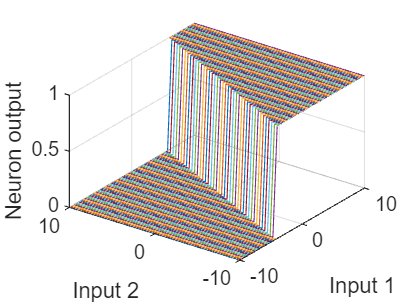


p = [2 3];
net_input = p*w'+b;
neuron_output = feval(func, net_input);

[p1,p2] = meshgrid(-10:.25:10);
z = feval(func, [p1(:) p2(:)]*w'+b );
z = reshape(z,length(p1),length(p2));
plot3(p1,p2,z);
grid on;
xlabel('Input 1');
ylabel('Input 2');
zlabel('Neuron output');

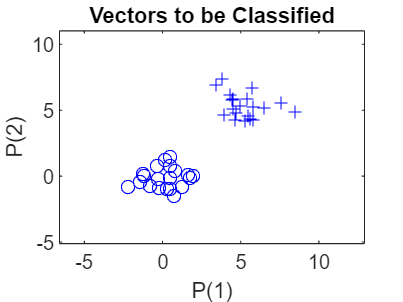

close all, clear all, clc
% number of samples of each class
N = 20;
% define inputs and outputs
offset = 5; % offset for second class
x = [randn(2,N) randn(2,N)+offset]; % inputs
y = [zeros(1,N) ones(1,N)]; % outputs
% Plot input samples with plotpv (Plot perceptron input/target vectors)
figure(1)
plotpv(x,y);

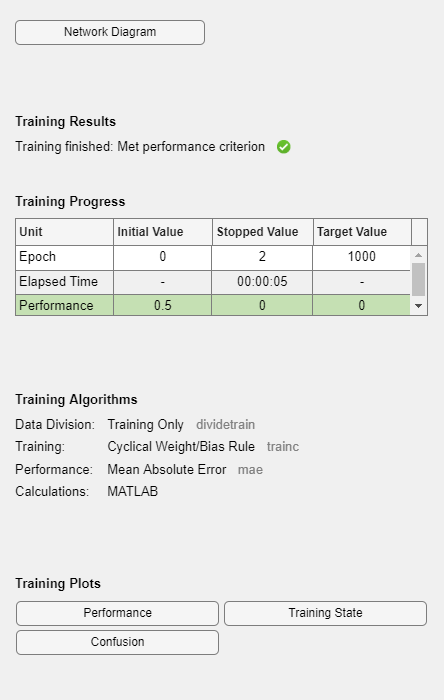

net = perceptron;
% Take a look to the default parameters of this perceptron. Notice that the performance/cost %function used is
%mae (mean absolute error), the training function is trainc (trains a network %with weight and bias learning rules
%with incremental updates) and the transfer function %used is hardlim (Hard-limit).
net = train(net, x, y);

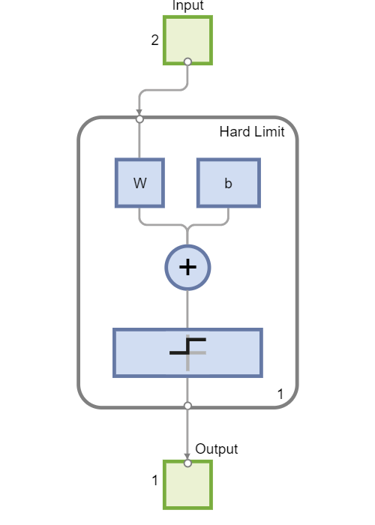

view(net);

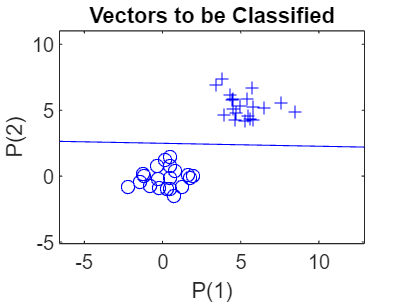

figure(1)
plotpc(net.IW{1},net.b{1});

% Plot a classification line on a perceptron vector plot

ans = -5

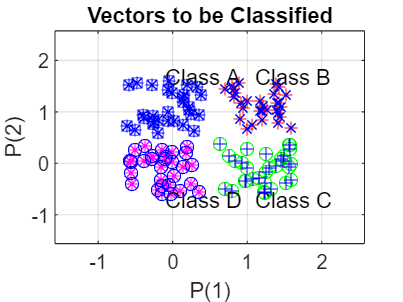

close all, clear all, clc
% number of samples of each class
K = 30;
% define classes
q = .6; % offset of classes
A = [rand(1,K)-q; rand(1,K)+q];
B = [rand(1,K)+q; rand(1,K)+q];
C = [rand(1,K)+q; rand(1,K)-q];
D = [rand(1,K)-q; rand(1,K)-q];

plot(A(1,:),A(2,:),'bs')
hold on
grid on
plot(B(1,:),B(2,:),'r+')
plot(C(1,:),C(2,:),'go')
plot(D(1,:),D(2,:),'m*')
% text labels for classes
text(.5-q,.5+2*q,'Class A')
text(.5+q,.5+2*q,'Class B')
text(.5+q,.5-2*q,'Class C')
text(.5-q,.5-2*q,'Class D')

a = [0 1]';
b = [1 1]';
c = [1 0]';
d = [0 0]';

P = [A B C D];
% define targets
T = [repmat(a,1,length(A)) repmat(b,1,length(B)) ... % repmat: Replicate and tile an array
repmat(c,1,length(C)) repmat(d,1,length(D)) ];
plotpv(P,T);

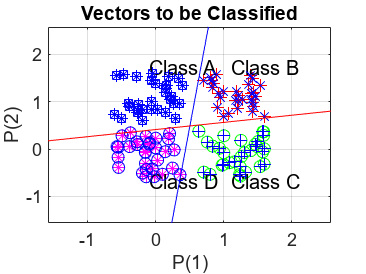

net = perceptron;
E = 1;
net.adaptParam.passes = 1;
linehandle = plotpc(net.IW{1},net.b{1});
n = 0;
while (sse(E) & n<1000) % sse: Sum squared error or mae: mean absolute error
n = n+1;
[net,Y,E] = adapt(net,P,T);
linehandle = plotpc(net.IW{1},net.b{1},linehandle);
drawnow;
pause(2); % 2 seconds pause
end

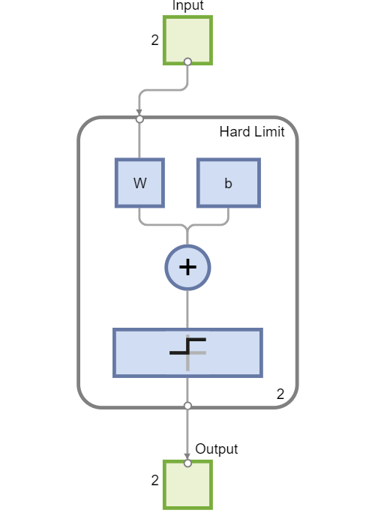

view(net);

p = [0.5; -1]

p =     0.5000
   -1.0000


y = net(p)

y =      1
     0
